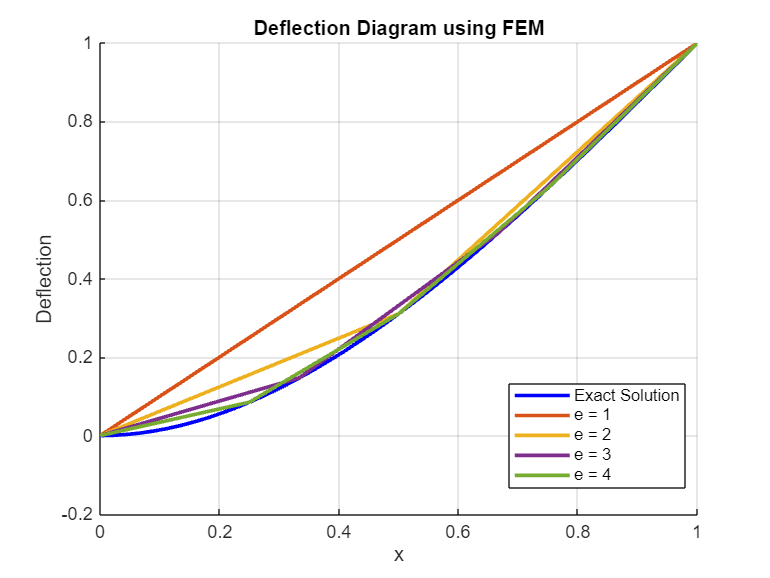

clc; 
clear;
syms x h a

elements = [1,2,3,4];
% Initialize cell arrays for storing outputs
deflections = cell(length(elements), 1);
slopes = cell(length(elements), 1);
BMoments = cell(length(elements), 1);
SFs = cell(length(elements), 1);
Xs = cell(length(elements), 1);

% Loop over each element count
for idx = 1:length(elements)
    e = elements(idx);
    f = 0;

    % No of Nodal points
    nodes =e+1;
    
    % numerical values for a, c, and h
    a_num = 1;
    % domain of X
    x0 = 0;
    xn = 1;
    
    P = 3; % hermitie cubic shape Functions
    
    phi_e = H_Cubic_beam_shapefunction_x(x0);
    
    % Element length
    h_num = (xn - x0) / e;
    
    DOF_e =4;
    %Degree of Freedom per element
    
    
    % Local stiffness matrix
    KNM_local = zeros(DOF_e, DOF_e, 'sym');
    CNM_local = zeros(DOF_e, DOF_e, 'sym');
    
    
    for N = 1:DOF_e
        for M = 1:DOF_e
            % Integrate to get the local stiffness matrix
            KNM_local(N, M) = int(a * diff(phi_e(N), x,2) * diff(phi_e(M), x,2),0,h_num);
            CNM_local(N, M) = int( phi_e(N) * phi_e(M), x, 0, h);
        end
    end
    
    
    
    % Substitute values into the local  matrices
    KNM_local_sub = double(subs(KNM_local, {a, h}, {a_num,h_num}));
    CNM_local_sub = double(subs(CNM_local, h, h_num));
    
    
    
    
    
    % Define degrees of freedom per node
    DOF_e = 2;
    
    % Total degrees of freedom
    total_DOF = nodes * DOF_e;
    
    % Initialize global stiffness matrix
    K_global = zeros(total_DOF);
    C_global = zeros(total_DOF);
    
    
    % Assemble the global stiffness matrix
    for i = 1:e
        % Global DOF indices for the current element
        start_index = (i-1) * DOF_e + 1;
        end_index = start_index + 2 * DOF_e - 1;
    
        % Assign local to global
        global_indices = start_index:end_index;
        K_global(global_indices, global_indices) = K_global(global_indices, global_indices) + KNM_local_sub;
        C_global(global_indices, global_indices) = C_global(global_indices, global_indices) + CNM_local_sub;
    end
    
    
    
    
    KC_global = K_global + C_global;
    
    
    Fv =  zeros(total_DOF,1);
    
    KC_global(1,:)= [1,zeros(1, total_DOF-1)];
    KC_global(2,:)= [0,1,zeros(1, total_DOF-2)];
    
    KC_global(end-1,:)= [zeros(1, total_DOF-2),1,0];
    
    Fv(1) =0;
    Fv(2) = 0;
    Fv(end-1)=1;
    
    vv_global = zeros(total_DOF,1);
    
    
    X = x0:h_num:xn;
    
    Gv = Fv + vv_global;
    
    UVUV = KC_global\Gv;
    
    UV = columnVectorToMatrix(UVUV);
    
    U = UV(:,1);
    V = UV(:,2);
% Extract results
    deflections{idx} = UV(:,1);
    slopes{idx} = UV(:,2);
    Xs{idx} = X;
    
   
end
    
syms x y(x) e 
Y1 = diff(y);
Y2 = diff(y,x,2);

ode = diff(y,x,4)+y==0;

cond1=y(0)==0;
cond2=Y1(0)==0;
cond3=Y2(1)==0;
cond4=y(1)==1;

conds = [cond1 cond2 cond3 cond4];

ysol(x)=dsolve(ode,conds);
ysol = vpa(simplify(ysol));
    
% Plotting results for all element configurations
figure;
hold on;
fplot(ysol,[0,1], "b", "LineWidth", 2, "DisplayName", "Exact Solution")
 % Colors for different element counts
for idx = 1:length(elements)
    plot(Xs{idx}, deflections{idx}, 'LineWidth', 2, 'DisplayName', sprintf('e = %d', elements(idx)));
    hold on;
end
xlabel('x');
ylabel('Deflection');
title('Deflection Diagram using FEM');
legend('Location', 'best');
grid on;
hold off;

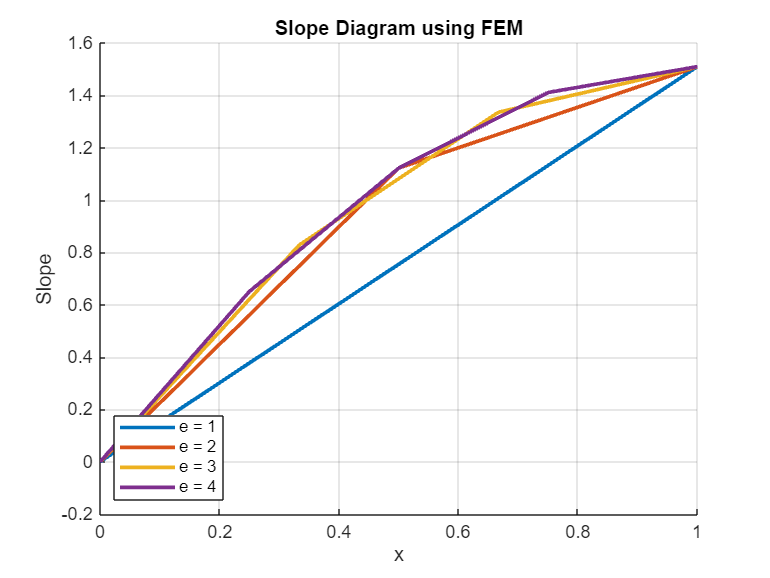


figure;
hold on;
for idx = 1:length(elements)
    plot(Xs{idx}, slopes{idx}, 'LineWidth', 2, 'DisplayName', sprintf('e = %d', elements(idx)));
end
xlabel('x');
ylabel('Slope');
title('Slope Diagram using FEM');
legend('Location', 'southwest');
grid on;
hold off;

function phi_e = H_Cubic_beam_shapefunction_x(x0)
    %Hermite cubic shape functions
    % Define symbolic variables
    syms x x1 h real;

    % in this formula x1 is starting point of the element

    % Define the Hermite cubic shape functions as provided
    N1 = 1 - (3*((x - x1)/h)^2) + (2*((x - x1)/h)^3);


    % for JN reddy N2 here assume inverted slope, So negative must be added for N2 and N4,
    % I'm following Dixit notation, ( Notes Only N2 and N4 are Different )

    N2 = (x - x1) * ((1-((x - x1)/h))^2);
    N3 = (3*((x - x1)/h)^2) - (2*((x - x1)/h)^3);
    N4 = (x - x1)*(((-((x - x1)/h)) + (((x - x1)/h)^2)));
    
    phi_e = sym(zeros(4,1));
    
    phi_e(1) = N1;
    phi_e(2) = N2;
    phi_e(3) = N3;
    phi_e(4) = N4;
    phi_e = subs(phi_e,x1,x0);

end
function B = matrixToColumnVector(A)
    % matrixToColumnVector converts a n x 2 matrix into a 2n x 1 column vector.

    % Check if the input matrix A has exactly 2 columns
    if size(A, 2) ~= 2
        error('Input matrix must have exactly 2 columns');
    end

    % Reshape the matrix A to a column vector
    B = reshape(A', [], 1);

    % Optionally, display the output vector
    % disp(B);  % Uncomment this line if you want to display the vector
end
function A = columnVectorToMatrix(B)
    % columnVectorToMatrix converts a 2n x 1 column vector into a n x 2 matrix.

    % Check if the length of vector B is even
    if mod(length(B), 2) ~= 0
        error('Length of input vector must be even');
    end

    % Calculate the number of rows for the matrix A
    numRows = length(B) / 2;

    % Reshape the vector B to a matrix A of size n x 2
    A = reshape(B, 2, numRows)';

    % Optionally, display the output matrix
    % disp(A);  % Uncomment this line if you want to display the matrix
end


